## Modulating Signal 

- What signal to use

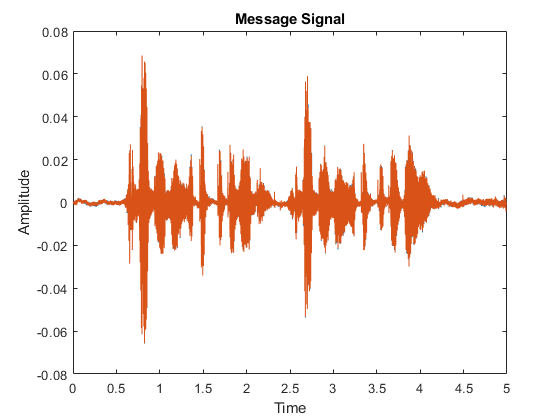

%% Read the audio signal [Modulating Signal]
[Message, Fs] = audioread('epic_voice.wav');
sound(Message,Fs)

%Message Signal Info
Message_Signal = Message';
N = length(Message_Signal);

time = N/Fs;


t = (0:1/Fs:time-1/Fs);

%% Plot Audio Signal
figure(1); plot(t,Message_Signal);
shg;
xlabel ('Time');
ylabel('Amplitude');
title('Message Signal');

## Modulate the Signal 

- Modulation Index = 1

- Carrier Info: Fc = 

%Modulation Index
A = 1;

% Carrier Info
Fc = 1135000

Fc = 1135000

Carrier_Signal = (A*cos(2*pi*Fc*t))

Carrier_Signal =     1.0000   -0.6088   -0.2588    0.9239   -0.8660    0.1305    0.7071   -0.9914    0.5000    0.3827   -0.9659    0.7934   -0.0000   -0.7934    0.9659   -0.3827   -0.5000    0.9914   -0.7071   -0.1305    0.8660   -0.9239    0.2588    0.6088   -1.0000    0.6088    0.2588   -0.9239    0.8660   -0.1305   -0.7071    0.9914   -0.5000   -0.3827    0.9659   -0.7934    0.0000    0.7934   -0.9659    0.3827    0.5000   -0.9914    0.7071    0.1305   -0.8660    0.9239   -0.2588   -0.6088    1.0000   -0.6088


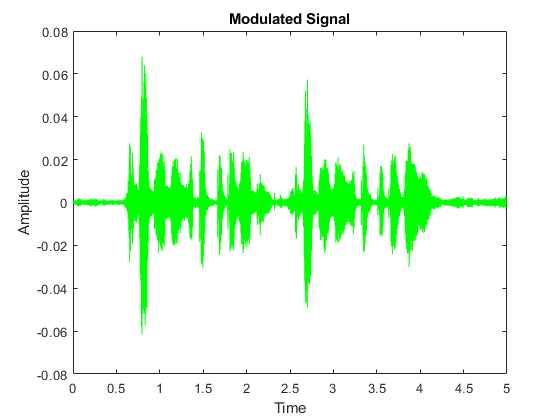

sound(Carrier_Signal, Fs)

%Modulating the Signal

Modulated_Signal = Message_Signal.*Carrier_Signal;
sound(Modulated_Signal, Fs)
figure(2); plot(t,Modulated_Signal,'g');
shg;
xlabel ('Time');
ylabel('Amplitude');
title('Modulated Signal');

## Amplify the Signal

- Voltage Gain = 0.5

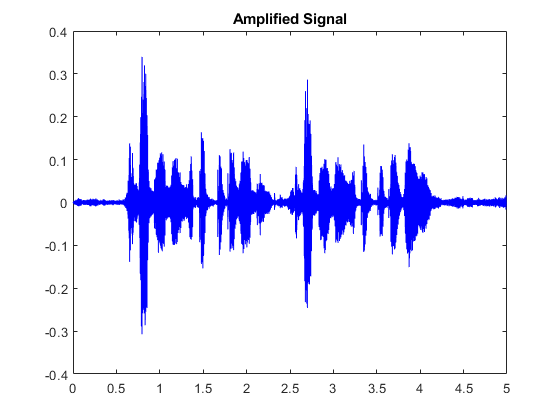

Amplified1 = 5*Modulated_Signal;
sound(Amplified1, Fs)
plot(t,Amplified1,'b')
title('Amplified Signal')

## Add Noise

- Add White Gaussian Noise (S/N = 

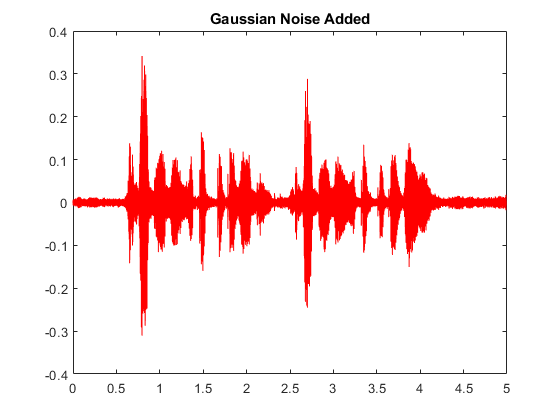

Signal_With_Noise = awgn(Amplified1,53);
sound(Signal_With_Noise,Fs)
plot(t,Signal_With_Noise,'r')
title('Gaussian Noise Added')

## Demodulate the Signal

- Demodulating Circuit = 

%Bandpass filter
Frequency1 = 20/(Fs/2)

Frequency1 = 8.3333e-04

Frequency2 = Fc/(Fs/2)

Frequency2 = 47.2917

Order = 2

Order = 2

% error vvvvv
[num,den]=butter(Order,[Frequency1,Frequency2],'bandpass')

Error using butter>butterImpl (line 85)
The cutoff frequencies must be within the interval of (0,1).

Error in butter (line 59)
        [varargout{1:nargout}] = butterImpl(n,Wn,varargin{:});


%Demodulation
Demodulated1 = filter(num,den,Signal_With_Noise)
Demodulated2 = 2 * Demodulated1 .* Carrier_Signal
[E,F]=butter(Order*2,(Fc/2)/Fs,'low')
Demodulated3= filter(E,F,Demodulated2)
en=lowpass(envelope(Modulkated_lc), 0.2, dt)

%Plotting
plot(t,Demodulated2,'r')
title('Demodulated Signal')


## Amplify the Signal

- Voltage Gain = 

Amplified1 = 5*Demodulated2;
sound(Demodulated2, Fs, 8)


## Recover the Received Signal

- Show Graph & Play Audio

plot(t,Demodulated2,'b')
title('Demodulated Signal')
